# Demo of moistAir class usage

## Create stream

% create stream using degC and relative moisture.
% default flow 1kg/s
air_30C_50RH = moistAir(30, 0.5);

## Change stream properties

% create basic air stream
%   _w: water
%   _da: dry air
air = moistAir(30, 0.5);

% change stream temperature by degC, retain vapour content
air.t = 50;
% change stream temperature by degK, retain vapour content
air.T = 273.15 + 50;
% change relative humidity, retain temperature
air.rh = 0.3;
% change W(mixing ratio), W = M_w/M_da. See ASHRAE Handbook for detail
air.W = 0.1;
% change mass flow rate qm, kg/s, retain temp. & vapour content
air.qm = 2;
% change volumetric flow qv, m3/s, reain temp & vapour content
air.qv = 1;
% change enthalpy kJ/kg
air.h = 280;
% change enthalpy based on dry air, kJ/kg_da
air.h_da = 280;


## Query derived properties

% get saturate pressure Pa at certain temp. degC
moistAir.p_vsat(30); % 1: using static method
air.pws; % 2: using object method

% dew point not available yet, under development


## Manipulate streams

% merge streams using "+". Energy conservation applied to get mixture temp.
air_stream_1 = moistAir(20, 0.3);
air_stream_2 = moistAir(30, 0.5);
air_stream_1 + air_stream_2;

% manage stream flow by using "*". Temp. and moisture remain constant,
% flow rate multiplied
air_stream = moistAir(30,0.5);
air_stream.qm = 1;
air_stream = air_stream * 2;

% add moisture to stream (const pressure moisturizing process, energy balanced)
% add_moisture(mass_flow_rate, temp_in_degC, optionalphase)
air_stream = air_stream.add_moisture(0.1, 30);% default "v" for vapor
air_stream = air_stream.add_moisture(0.1, 10, "l"); % "l" for liquid phase and "s" for solid
air_stream = air_stream.add_moisture(0.001, -5, "s");

% remove fog/frost and update state to saturated if RH > 100%
air_stream = air_stream.update_to_sat();

% get equilibrium state under certain circulation ratio
air_stream_1 = moistAir(20, 0.3);
air_stream_2 = moistAir(30, 0.5);
moistAir.get_eq_air(air_stream_1, air_stream_2, 0.5);


## Array usage

% create and index stream by arrays of properties.
% note array length of different properties must be either equal or 1
% 1: temp in array, RH, qm all same
air_stream = moistAir([20, 30, 40], 0.3);
air_stream(2) % get stream t=30,rh=0.3

ans =   moistAir - 属性:

         t: 30
         W: 0.0079
        qm: 1
       Rda: 287.0425
        Rw: 461.5236
         T: 303.1500
       rho: 1.1589
    rho_da: 1.1498
         h: 50.0295
      h_da: 50.4256
        qv: 0.8629
       pws: 4.2460e+03
       xws: 0.0419
        Ws: 0.0272
        pw: 1.2738e+03
        xw: 0.0126
        rh: 0.3000


% 2: temp and RH in array
air_stream = moistAir([20, 30, 40], [0.3, 0.4, 0.5]);
air_stream(2) % get stream t=30,rh=0.4

ans =   moistAir - 属性:

         t: 30
         W: 0.0106
        qm: 1
       Rda: 287.0425
        Rw: 461.5236
         T: 303.1500
       rho: 1.1570
    rho_da: 1.1449
         h: 56.6882
      h_da: 57.2892
        qv: 0.8643
       pws: 4.2460e+03
       xws: 0.0419
        Ws: 0.0272
        pw: 1.6984e+03
        xw: 0.0168
        rh: 0.4000


% 3: temp and RH single, qm in array
air_stream = moistAir(20, 0.5);
air_stream.qm = [1,2,3];
air_stream(3) % get stream t=20, rh=0.5, qm=3

ans =   moistAir - 属性:

         t: 20
         W: 0.0073
        qm: 3
       Rda: 287.0425
        Rw: 461.5236
         T: 293.1500
       rho: 1.1989
    rho_da: 1.1903
         h: 38.2738
      h_da: 38.5518
        qv: 2.5023
       pws: 2.3388e+03
       xws: 0.0231
        Ws: 0.0147
        pw: 1.1694e+03
        xw: 0.0115
        rh: 0.5000



% "+" and "*" works in array form
% note that here behavior of "+" and "*"  is a little bit different
% "+" extend other properties to same dimension while "*" does not
air_stream = moistAir(20, 0.5);
air_stream.qm = [1,2,3];
air_stream + air_stream;
air_stream * 2;

% following functions can't work in array form yet, consider extract state point first
% air_stream = moistAir([20, 30, 40], [0.3, 0.4, 1.5])
% air_stream.update_to_sat


## Draw state point on diagram

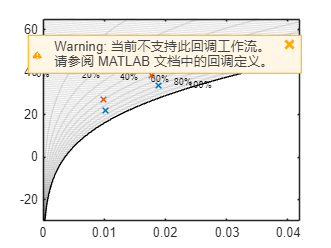

air_stream_1 = moistAir([20, 30, 40], 0.7);
air_stream_2 = moistAir([25,35,45], 0.5);
moistAir.plot_enth_moisture_diagram(air_stream_1, air_stream_2);